% File.mlx   --- 无效代码。
clear all-;
clc;
A=readmatrix("result.xls")

A =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN  101.3000  103.1000   99.5000  100.5000  101.5000  102.2000  100.8000  100.7000  101.5000  104.0000   99.2000   99.5000
       NaN  101.2000  101.8000  101.0000  100.5000  101.2000  100.8000  100.6000  100.9000  101.2000  102.1000   99.2000  100.0000
       NaN  101.8000  104.3000   99.8000  100.5000  101.7000  102.9000  101.2000  100.5000  101.6000  103.4000   99.2000   99.9000
       NaN  704.6000  710.8000  704.5000  703.5000  703.2000  709.4000  708.5000  703.2000  705.5000  712.1000  710.3000  700.7000
       NaN  102.0000  105.0000   99.7000  100.5000  101.9000  103.4000  101.1000  100.4000  101.5000  103.2000   99.5000   99.8000
       NaN  101.2000  102.6000   99.6000  100.6000  101.0000  102.1000  101.3000  100.3000  101.1000  101.6000  100.0000  100.0000
       NaN  100.7000  101.7000  100.2000  100.4000  100.4000  101.3000  101.200

%删去第一行，第一列,第四行
A(1,:)=[];
A(:,1)=[];
A(4,:)=[];
A

A =   101.3000  103.1000   99.5000  100.5000  101.5000  102.2000  100.8000  100.7000  101.5000  104.0000   99.2000   99.5000
  101.2000  101.8000  101.0000  100.5000  101.2000  100.8000  100.6000  100.9000  101.2000  102.1000   99.2000  100.0000
  101.8000  104.3000   99.8000  100.5000  101.7000  102.9000  101.2000  100.5000  101.6000  103.4000   99.2000   99.9000
  102.0000  105.0000   99.7000  100.5000  101.9000  103.4000  101.1000  100.4000  101.5000  103.2000   99.5000   99.8000
  101.2000  102.6000   99.6000  100.6000  101.0000  102.1000  101.3000  100.3000  101.1000  101.6000  100.0000  100.0000
  100.7000  101.7000  100.2000  100.4000  100.4000  101.3000  101.2000  100.2000  100.9000  101.9000  101.2000   99.8000
  100.3000  100.4000  101.3000  100.5000  100.2000  100.6000  101.4000  100.6000  100.4000  100.7000  101.8000  100.2000
  100.2000   99.8000  101.1000  100.6000   99.9000  100.6000  101.2000  100.4000  100.6000  101.6000  102.1000   99.9000
  100.1000  101.6000  101.20

beijing=A(:,1:4)

beijing =   101.3000  103.1000   99.5000  100.5000
  101.2000  101.8000  101.0000  100.5000
  101.8000  104.3000   99.8000  100.5000
  102.0000  105.0000   99.7000  100.5000
  101.2000  102.6000   99.6000  100.6000
  100.7000  101.7000  100.2000  100.4000
  100.3000  100.4000  101.3000  100.5000
  100.2000   99.8000  101.1000  100.6000
  100.1000  101.6000  101.2000  100.6000
  100.1000   99.7000  101.4000  100.3000


tianjin=A(:,5:8)

tianjin =   101.5000  102.2000  100.8000  100.7000
  101.2000  100.8000  100.6000  100.9000
  101.7000  102.9000  101.2000  100.5000
  101.9000  103.4000  101.1000  100.4000
  101.0000  102.1000  101.3000  100.3000
  100.4000  101.3000  101.2000  100.2000
  100.2000  100.6000  101.4000  100.6000
   99.9000  100.6000  101.2000  100.4000
   99.8000  101.6000  101.0000  100.6000
  100.0000   99.8000  101.3000  100.7000


hebei=A(:,9:12)

hebei =   101.5000  104.0000   99.2000   99.5000
  101.2000  102.1000   99.2000  100.0000
  101.6000  103.4000   99.2000   99.9000
  101.5000  103.2000   99.5000   99.8000
  101.1000  101.6000  100.0000  100.0000
  100.9000  101.9000  101.2000   99.8000
  100.4000  100.7000  101.8000  100.2000
  100.6000  101.6000  102.1000   99.9000
  100.7000  103.1000  102.5000  100.4000
  100.3000  100.0000  103.2000  100.6000



%%AHP：
%最大最小值归一化
%beijing_1T=mapminmax(beijing,0,1)
%tianjin_1=mapminmax(tianjin,0,1)
%hebei_1=mapminmax(hebei,0,1)

%构建判断矩阵
%对于居民消费，食品烟酒，衣着类，居住类
Judge=[1,3,5,1/3;
       1/3,1,3,5;
       1/5,1/3,1,3;
       3,1/5,1/3,1];

%% 一致性检验
[~,n]=size(Judge);
[v,d]=eig(Judge);
r=max(diag(d));
CI=(r-n)/(n-1);
RI=[0 0 0.58 0.90 1.12 1.24 1.32 1.41 1.45 1.49 1.52 1.54 1.56 1.58 1.59];
CR=CI/RI(n);
if CR<0.1
    CR_Result='通过一致性检验';
else
    CR_Result='未通过一致性检验';
end

%% 计算权向量
w=v(:,1)/sum(v(:,1));
w=w';

% 结果输出
disp(['一致性指标：CI=' num2str(CI)]);

一致性指标：CI=0.75645


disp(['一致性比率：CR=' num2str(CR)]);

一致性比率：CR=0.8405


disp(['一致性检验结果:' CR_Result]);

一致性检验结果:未通过一致性检验


disp(['特征值：' num2str(r)]);

特征值：6.2693


disp(['特征向量' num2str(w)]);

特征向量0.3317     0.30663     0.15159     0.21008






%%熵权法
%指标正向化处理后数据为data1
data=beijing;
data1=data;
%数据标准化 mapminmax对行进行标准化，所以转置一下
data2=mapminmax(data1',0.002,1); %标准化到0.002-1区间
data2=data2';
 
%得到信息熵
[m,n]=size(data2);
p=zeros(m,n);
for j=1:n
    p(:,j)=data2(:,j)/sum(data2(:,j));
end
for j=1:n
   E(j)=-1/log(m)*sum(p(:,j).*log(p(:,j)));
end
 
%计算权重
w=(1-E)/sum(1-E)

w =     0.3466    0.2564    0.2827    0.1143


 
%计算得分
s=data2*w'

s =     0.4607
    0.6024
    0.6542
    0.7095
    0.4712
    0.3498
    0.4156
    0.3767
    0.4602
    0.2841


Score=100*s/max(s);
disp('北京的10个月的得分为：')

北京的10个月的得分为：


disp(Score)

   64.9251
   84.9077
   92.1983
  100.0000
   66.4093
   49.2951
   58.5676
   53.0926
   64.8670
   40.0474







%用K-means聚类分析
%数据初始化
K = 3;  % 设置聚类中心个数
x = beijing;  % 假设数据集为 'beijing'
[s, ~] = size(x);  % 获取样本数目
z = x(1:K, :);  %选取前K个样本作为初始聚类中心
%这里选取初始聚类中心不具有随机性
z1 = zeros(K, size(x, 2));  % 初始化聚类中心矩阵

% 迭代寻找聚类中心
while true
    count = zeros(K, 1);  % 用于统计每个聚类中心的样本数量
    allsum = zeros(K, size(x, 2));  % 用于累加每个聚类中心的样本坐标
    
    for k = 1:s   % 对每个样本进行分类
        % 计算每个样本到所有K个聚类中心的距离
        distances = sqrt(sum((z - x(k, :)).^2, 2));  % 欧氏距离计算
        [~, cluster] = min(distances);  % 找到最近的聚类中心
        
        % 将样本分配给最近的聚类中心
        count(cluster) = count(cluster) + 1;
        allsum(cluster, :) = allsum(cluster, :) + x(k, :);
    end
    
    % 更新聚类中心
    for i = 1:K
        if count(i) ~= 0  % 防止出现分配空簇的情况
            z1(i, :) = allsum(i, :) / count(i);  % 计算每个簇的中心
        else
            z1(i, :) = z(i, :);  % 如果该簇没有样本，保持聚类中心不变
        end
    end
    
    % 判断聚类中心是否发生变化，若没有变化，则停止迭代
    if all(z == z1, 'all')
        break;
    else
        z = z1;  % 更新聚类中心
    end
end

% 结果显示
disp('聚类中心：')

聚类中心：


for i = 1:K
    disp(['(' num2str(z1(i, 1)) ',' num2str(z1(i, 2)) ')']);
end

(101.25,102.85)
(100.4333,100.8333)
(101.9,104.65)


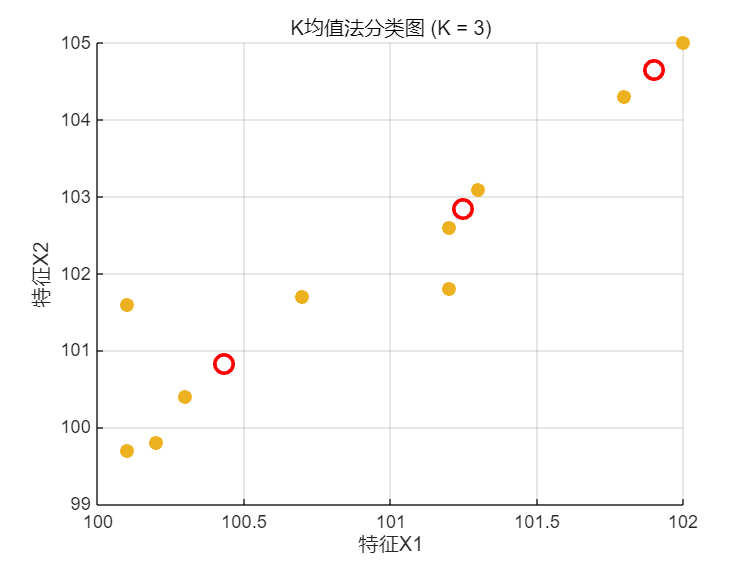


% 绘制结果
figure;
hold on;
colors = lines(K);  % 自动生成K种颜色
for i = 1:K
    scatter(x(:, 1), x(:, 2), 50, 'Marker', 'o', 'MarkerEdgeColor', colors(i,:), 'MarkerFaceColor', colors(i,:));  % 根据聚类中心绘制样本
end
scatter(z1(:,1), z1(:,2), 100, 'ro', 'LineWidth', 2);  % 聚类中心位置
title(['K均值法分类图 (K = ' num2str(K) ')']);
xlabel('特征X1');
ylabel('特征X2');
grid on;
hold off;

%我们定义这三个聚类中心代表：活跃月，普通月，萧条月
%根据这个图，计算每个点与聚类中心的距离，可以得到属于哪个月
%缺点：选取聚类中心不具有随机性
%无法多次运行k-mean 每次选随机的聚类中心
%结合多次运行的结果取平均的聚类中心


%画图
X=beijing(:,1)

X =   101.3000
  101.2000
  101.8000
  102.0000
  101.2000
  100.7000
  100.3000
  100.2000
  100.1000
  100.1000


Y=beijing(:,2)

Y =   103.1000
  101.8000
  104.3000
  105.0000
  102.6000
  101.7000
  100.4000
   99.8000
  101.6000
   99.7000


Z=beijing(:,3)

Z =    99.5000
  101.0000
   99.8000
   99.7000
   99.6000
  100.2000
  101.3000
  101.1000
  101.2000
  101.4000


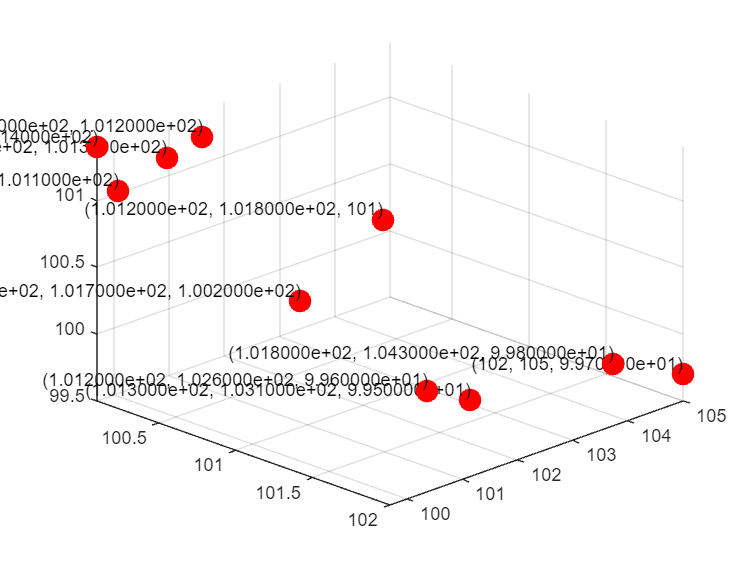

figure;
scatter3(X,Y,Z,150,'filled','MarkerFaceColor','r');
% 设置坐标轴的范围
axis tight;  % 紧缩坐标轴范围以适应数据
grid on;  % 显示网格

% 添加数据标签
for i = 1:length(X)
    text(X(i), Y(i), Z(i), sprintf('(%d, %d, %d)', X(i), Y(i), Z(i)), ...
         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10);
end
% 调整视角
view(45, 30);  % 设置视角，使得图形更易观察